# FMCW雷达系统信号处理建模与仿真

## 发射信号模型

雷达发射信号的模型可采用线性调频连续波（LFMCW） ，发射波形的信号形式为调频连续锯齿波。

理论上，发射信号的模型可以用以下公式表示

余弦实信号形式


$$x_{tx}(t)=A\cos\left(2\pi\left(f_0t+\frac{St^2}{2}\right)+\varphi_0\right)$$


复指数形式


$$s_t=A e^{j2\pi\left(f_0t+\frac{S t^2}{2}+\varphi_0\right)}
$$


矩形窗+复指数形式


$$s_t(t)=A\text{rect}\left(\frac{t}{\tau}\right)\mathrm{e}^{\mathrm{j}2\pi\left(f_0t+\frac{St^2}{2}+\varphi_0\right)}$$


但是由于我们在发射信号是，只有实数信号，而并非复数信号，只是在后续的ADC芯片中采用正交采样时，才把信号变为复信号。需要注意的是，这两种表达方式都是正确的，只是在后续的处理过程中，有一些不同。本文仍旧采用传统的实数信号表达方式。

## 雷达参数与目标参数设置

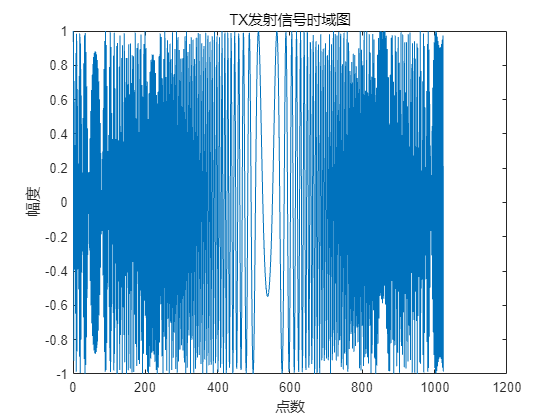

%% 微信公众号：调皮的连续波
%% 知乎：调皮连续波
%% 作者：调皮哥
%% 时间：2022年5月
%% 功能：FMCW雷达发射信号、回波信号、混频、距离维FFT、速度维FFT建模仿真。
%%=========================================================================
clear all;
close all;
clc;
%% 雷达系统参数设置
maxR = 200;           % 雷达最大探测目标的距离
rangeRes = 1;         % 雷达的距离分率
maxV = 70;            % 雷达最大检测目标的速度
fc= 77e9;             % 雷达工作频率 载频
c = 3e8;              % 光速

%% 用户自定义目标参数
r0 = 90; % 目标距离设置 (max = 200m)
v0 = 10; % 目标速度设置 (min =-70m/s, max=70m/s)


%% FMCW波形参数设置
B = c / (2*rangeRes);       % 发射信号带宽 (y-axis)  B = 150MHz
Tchirp = 5.5 * 2 * maxR/c;  % 扫频时间 (x-axis), 5.5= sweep time should be at least 5 o 6 times the round trip time
slope = B / Tchirp;         %调频斜率
endle_time=6.3e-6;          %空闲时间
f_IFmax= (slope*2*maxR)/c ; %最高中频频率
f_IF=(slope*2*r0)/c ;       %当前中频频率

Nd=128;                          %chirp数量 
Nr=1024;                        %ADC采样点数
vres=(c/fc)/(2*Nd*(Tchirp+endle_time));%速度分辨率
% Nr=1024*256;                %和频信号点数设置
Fs=Nr/Tchirp;                 %模拟信号采样频率

t=linspace(0,Nd*Tchirp,Nr*Nd); %发射信号和接收信号的采样时间，在MATLAB中的模拟信号是通过数字信号无限采样生成的。

Tx=zeros(1,length(t)); %发射信号
Rx=zeros(1,length(t)); %接收信号
Mix = zeros(1,length(t)); %差频、差拍、拍频、中频信号

r_t=zeros(1,length(t));
td=zeros(1,length(t));

%% 动目标信号生成

for i=1:length(t)
    
    r_t(i) = r0 + v0*t(i); % 距离更新
    td(i) = 2*r_t(i)/c;    % 延迟时间
    
    Tx(i) = cos(2*pi*(fc*t(i) + (slope*t(i)^2)/2)); % 发射信号 实数信号
    Rx(i) = cos(2*pi*(fc*(t(i)-td(i)) + (slope*(t(i)-td(i))^2)/2)); %接收信号 实数信号
    
    if i<=1024
         freq(i)=fc+slope*i; %发射信号时频图 只取第一个chirp
         freq_echo(i)=fc+slope*i;%回波信号频谱延迟
    end

    Mix(i) = Tx(i).*Rx(i);%差频、差拍、拍频、中频信号
end

%发射信号时域图
figure;
plot(Tx(1:1024));
xlabel('点数');
ylabel('幅度');
title('TX发射信号时域图');

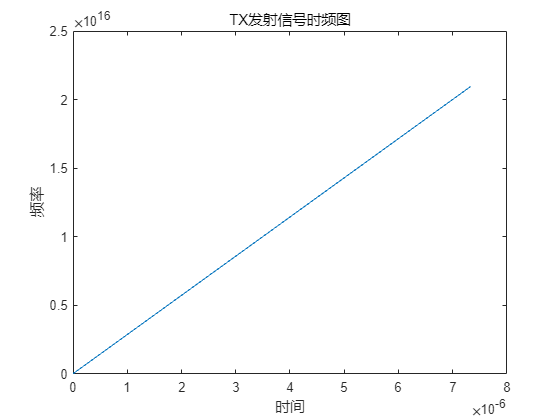


% %发射信号时频图
figure;
plot(t(1:1024),freq);
xlabel('时间');
ylabel('频率');
title('TX发射信号时频图');

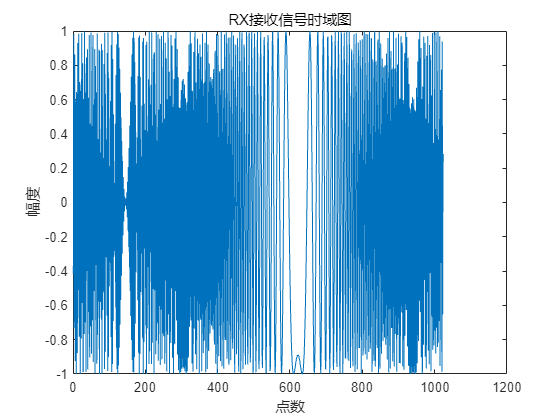


%接收信号时域图
figure;
plot(Rx(1:1024));
xlabel('点数');
ylabel('幅度');
title('RX接收信号时域图');

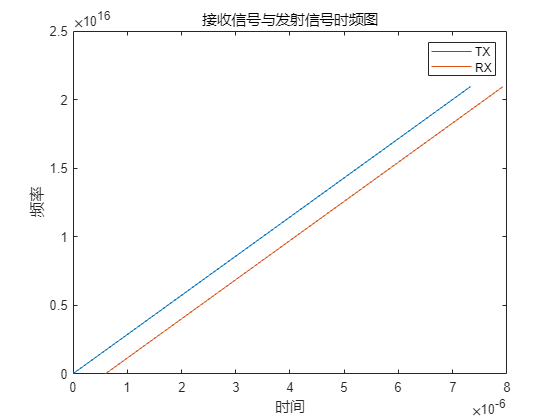


%接收信号与发射信号的时频图
figure;
plot(t(1:1024),freq);
hold on;
plot(td(1:1024)+t(1:1024),freq);
xlabel('时间');
ylabel('频率');
title('接收信号与发射信号时频图');
legend ('TX','RX');

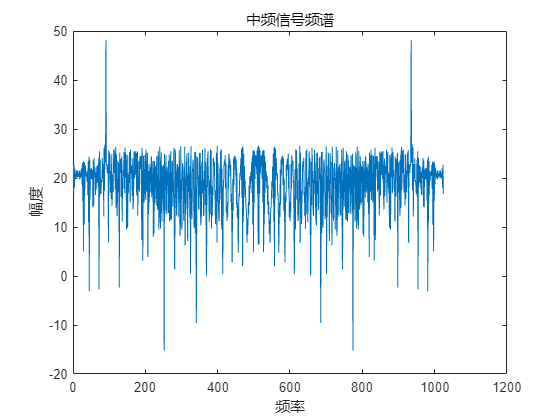


%中频信号频谱 和频信号观察
%figure;
% plot(db(abs(fft(Mix(1:1024*256)))));%查看宽带的和频信号 将chirp的点数改为1024*256即可看到有一个门信号，但注意计算机内存。
% xlabel('频率');
% ylabel('幅度');
% title('中频信号频谱');

figure;
plot(db(abs(fft(Mix(1:1024)))));%查看宽带的和频信号 将chirp的点数改为1024*256即可看到有一个门信号，但注意计算机内存。
xlabel('频率');
ylabel('幅度');
title('中频信号频谱');

**此时要注意，**本文采用“数字信号的形式”来模拟发射信号与回波信号，实际上是不会通过这种方式实现的，发射信号和回波信号都是模拟信号。因此在本文中，混频之后得到的中频信号只有单一的频谱，即只保留了混频乘法器积化和差公式后的“差频”信号，“和频”信号由于MATLAB采用数字信号的形式导致采样率过低，N/Tchirp=1024/Tchirp=139MHz，对“和频信号”相当于欠采样，因此并不会保留高频信号，只保留目标的最大中频信号（27.27MHz），从而MATLAB自身形成一个低通（或带通）滤波器。

如果想要看到“和频”信号，则可以通过增加发射信号点数的点数，相当于增加采样率的形式来观察，但由于数据量很大，雷达载波也很高，因此不建议大家尝试。调皮哥给大家尝试了，在MATLAB代码中约为35GHz，离77GHz还很远，相当于欠采样，但还可以采集到的部分高频信号。如图中所示，类似于门函数的频带就是和频信号。

% Nr=1024*256; 
% %中频信号频谱
% plot(db(abs(fft(Mix(1:1024*256)))));%查看宽带的和频信号 将chirp的点数改为1024*256即可看到有一个门信号，但注意计算机内存。
% xlabel('频率');
% ylabel('幅度');
% title('中频信号频谱');

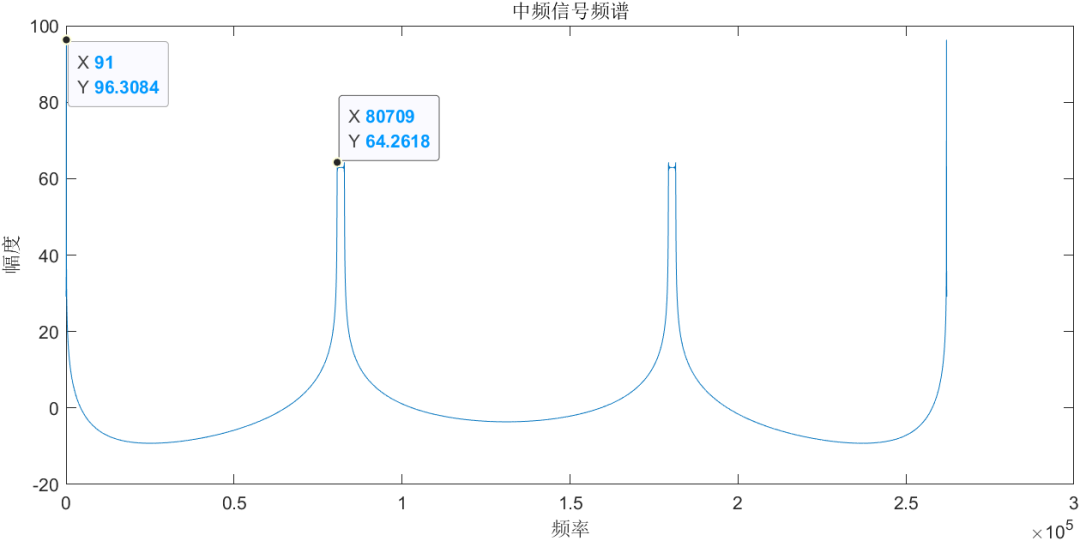

## 低通（带通滤波）

本文的FMCW雷达信号处理建模仿真，由于MATLAB采样点数问题，低通滤波器相当于自带。如若按照增加采样点数的方式来实现低通滤波器的模拟，则可以实现如图

%% 低通滤波 截止频率30MHz  采样频率120MHz
% Mix=lowpass(Mix(1:1024*256),30e6,120e6);
% plot(db(abs(fft(Mix(1:1024*256)))));
% xlabel('频率');
% ylabel('幅度');
% title('中频信号低通滤波器');

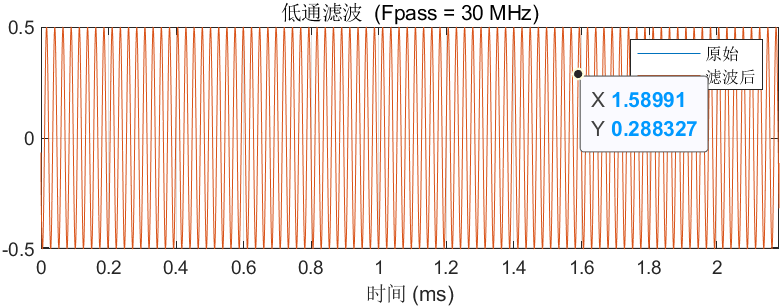

**图10 滤波后结果**

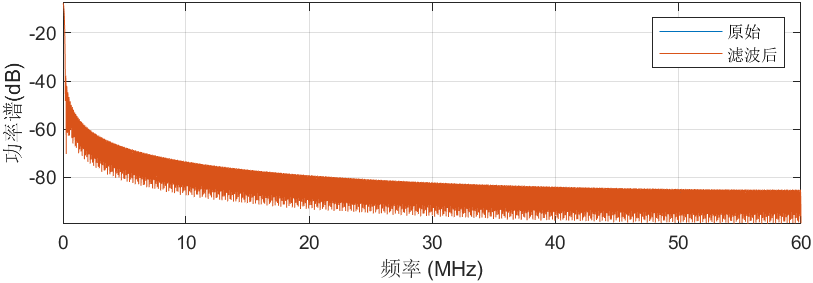

**图11 低通滤波幅频响应**

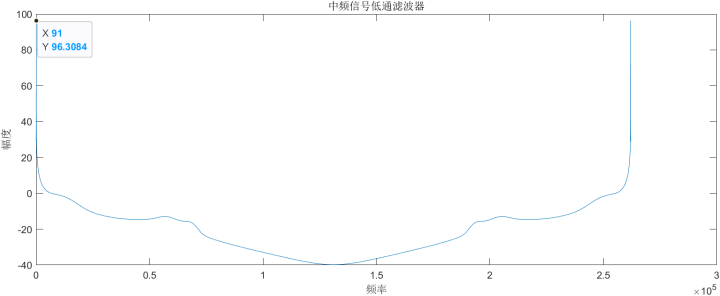

**图12 低通滤波结果**

放大后保留的频率如图13所示：

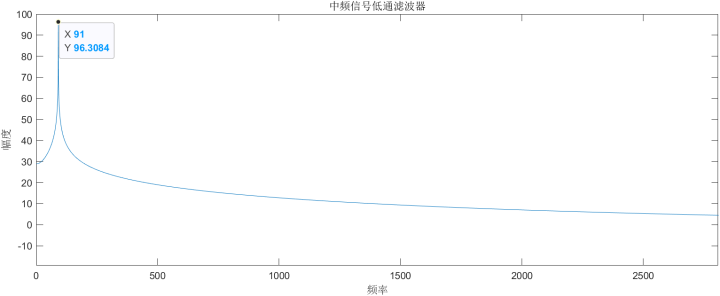

**图13 低通滤波结果（放大效果）**

## 距离估计

假设单个扫描周期 ADC采样点数为 1024， 采样频率为Fs=139MHz， 式中 n 为 FFT 谱峰对应的频点(Index）， 根据 T、 Fs、 N 之间的关系，距离与频率关系的公式可进一步化简为：


$$R=\frac{cTf_m}{2B}=\frac{cT}{2B}\frac{F_s}{N}n=\frac{c}{2B}\frac{TF_s}{N}n=\Delta R*K*n=K*\Delta R*n$$


其中，请注意，因为上述的采样点刚好是2的次幂，因此，计算之后系数K刚好为1，假如采样点数不是2的次幂，如200个点，然后进行256个点的FFT，那么K值就不能等于1。

将中频信号按照距离门点数、chirp脉冲数排列为二维矩阵，其时域谱如下图

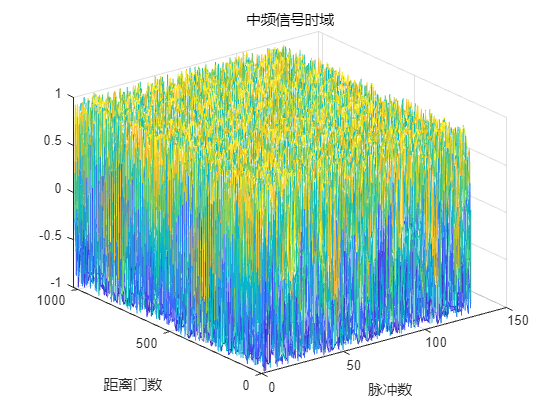


%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
signal = reshape(Mix,Nr,Nd);

figure;
mesh(signal);
xlabel('脉冲数')
ylabel('距离门数');
title('中频信号时域');

第一个chirp脉冲的距离维FFT结果，实信号FFT后频谱对称，只保留一半的频谱，即512个点，如下图

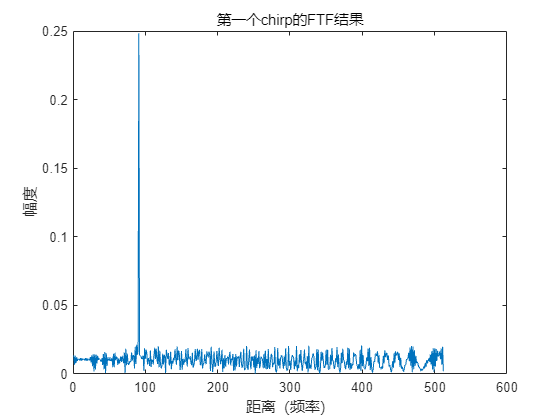

%% 距离维FFT
sig_fft = fft(signal,Nr)./Nr;
sig_fft = abs(sig_fft);
sig_fft = sig_fft(1:(Nr/2),:);

figure;
plot(sig_fft(:,1));
xlabel('距离（频率）');
ylabel('幅度')
title('第一个chirp的FTF结果')

在MATLAB中，对于距离维做FFT，目的就是找出中频频率峰值和频点，然后根据峰值所在的距离门号，解算出目标的距离。

如本文的距离门号为91，距离分辨率为1米，则真实距离为：（91-1）*1=90米，符合预先设定的目标参数值。

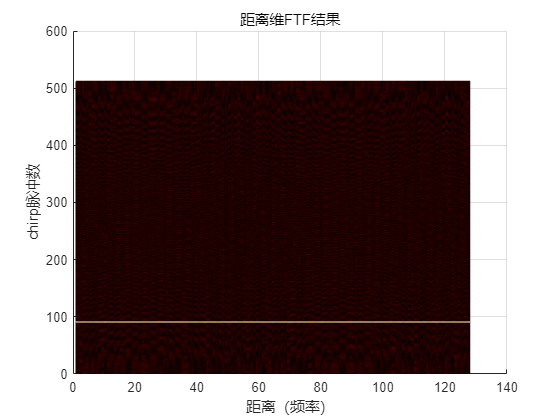


%% 距离FFT结果谱矩阵
figure;
mesh(sig_fft);
xlabel('距离（频率）');
ylabel('chirp脉冲数')
zlabel('幅度')
title('距离维FFT结果')
view(0,90)
colormap hot

## 速度估计

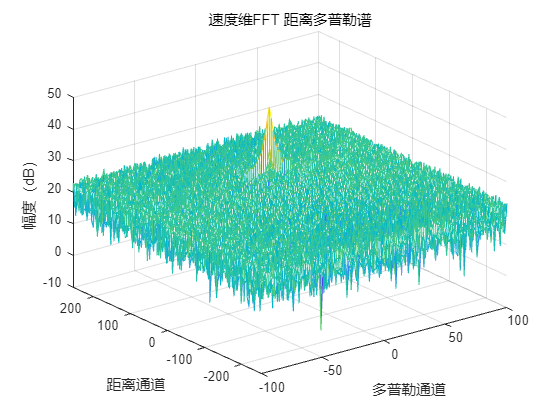

%% 速度维FFT

Mix=reshape(Mix,[Nr,Nd]);
sig_fft2 = fft2(Mix,Nr,Nd);

sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);

figure;
mesh(doppler_axis,range_axis,RDM);
xlabel('多普勒通道'); ylabel('距离通道'); zlabel('幅度（dB）');
title('速度维FFT 距离多普勒谱');

如本文的多普勒门号为10，速度分辨率为 vres= 1.1163m/s，则真实距离为：（10-1）* 1.1163 = 10.04m/s，符合预先设定的目标参数值，其中这里的速度分辨率vres是由雷达工程师自主设定的，在FMCW雷达中可以增加调频连续波的空闲时间来增加速度分辨率，但要注意与最大不模糊速度保持平衡。

## 复指数形式

Tx_s = zeros(size(Tx));
Rx_s = zeros(size(Rx));
Mix_s = zeros(size(Mix));
%% 生成信号
for i = 1: length(t)
    r_t(i) = r0 + v0*t(i);  % 距离更新
    td(i) = 2*r_t(i)/c;    % 延迟时间
%     Tx(i) = cos(2*pi*(f_0*t(i) + (slope*t(i)^2)/2)); % 发射信号 实数信号
    Tx_s(i) = exp(1j*2*pi*(fc*t(i) + (slope*t(i)^2)/2));
%     Rx(i) = cos(2*pi*(f_0*(t(i)-tau(i)) + (slope*(t(i)-tau(i))^2)/2)); %接收信号 实数信号
    Rx_s(i) = exp(1j*2*pi*(fc*(t(i)-td(i)) + (slope*(t(i)-td(i))^2)/2));

    Mix_s(i) = Tx_s(i).*Rx_s(i);%差频、差拍、拍频、中频信号
end

%发射信号时域图
figure;
plot(real(Tx_s(1:Nr)));
xlabel('点数');
ylabel('幅度');
title('TX发射信号时域图');

#  利用希尔伯特变换（Hilbert）将中频实信号转换为IQ信号

## 1.为什要利用希尔伯特变换？

我们知道，在实际的物理世界里，是不存在复信号的，所谓的复信号，其实是在ADC采样之后生成的，我们称之为正交采样复基带信号。因为复基带信号可以提高3dB左右的信噪比，其傅里叶变换频谱是单边带，且正交采样对于ADC的性能要求更低，所以我们一般都会采用这种方法。

但是，在MATLAB中进行仿真时，我们一般很难进行模拟信号进行仿真，除非使用特殊的射频仿真工具。

因此，我们需要知道在MATLAB中，无论是雷达的发射信号、回波信号，还是混频后的中频信号、ADC采样后的基带信号都是实信号。但是，这离我们需要的复信号还不是最优的结果，实信号的傅里叶变换是双边带，我们只能利用其一边的频带，这就需要牺牲最远探测的距离。

如果我们直接将发射信号和回波信号写为复指数的形式，那我们想要直接理解复信号的实际含义，以及雷达辐射信号的真正物理工作方式，是很难的。很多学习了很久雷达，以为雷达一直辐射的是复信号，其实并不是，只要是在物理硬件上走的信号，都是实信号，复信号可以看做是一个相对的概念，即有实部和虚部。而这两部分均是由两路信号组合而产生的，人们采用复信号的形式有很多优点，就如上所述。

这篇文章主要是帮助雷达初学者更清楚理解实信号和复信号，以及雷达的发射信号的形式。在数学上，我们为了表示方方便，大家都习惯于将所有信号写为复信号形式，更加利于分析，但实际上写为实信号形式是更加贴近于现实物理世界的。在之前的文章中，我也提到过，发射信号的模型有很多种写法

这些形式的物理本质都是一样的，只是为了更清楚的描述雷达发射信号，我们更愿意采样容易理解的方式。还是那句话说得好：世界的本质都是一样的，我们只是用不同的方法解释世界而已。

因此，在MATLAB中模拟雷达发射信号与回波信号混频后，并从实信号转变为复信号，就需利用希尔伯特变换。

## 2.希尔伯特变换原理

希尔伯特变换的物理意义十分简单：**把信号的所有频率分量的相位推迟90度。**

利用公式表达，若原始信号为：


$$x(t)=\int_0^\infty A(\omega)\cos(\omega t+\varphi(\omega))\text{d}\omega$$


则经过希尔伯特变换后的信号为：


$$y(t)=\int_0^\infty A(\omega)\sin(\omega t+\varphi(\omega))d\omega$$


上述物理意义，表明如果一个信号是实信号，那么经过希尔伯特变换则可以变为复信号（实质为解析信号）。

在MATLAB中做信号希尔伯特变换有两条命令：

以常用的第一种为例，`x = hilbert(xr)`是对信号`xr`做希尔伯特变换，返回的是一个解析信号`x`，`x`实部是`xr`本身，虚部是`xr`的希尔伯特变换。

因此，这样我们就可以得到单边带的频谱。

## 3.示例

下面两幅图是将实信号经过希尔伯特变换后，分别做距离维FFT、速度维FFT后的结果，可以看出，结果是单边带频谱，这样做的目的其实和截取实信号双边带频谱的一半在结果上，区别不大。只是调皮哥个人对这种方式感到好奇而做的一个验证。

无论是距离维FFT和速度维FFT结果，在另一半上的幅度很低，基本为0。因为时域卷积，频域相乘，希尔伯特变换后的频谱相当于原信号的频谱乘以H(w)，故而希尔波特变换相当于一个正交滤波器，信号经希尔波特变换后，在频域各频率分量的幅度保持不变，但相位将出现90°相移。即对正频率滞后90度 ，对负频率导前90度 ，因此希尔波特变换器又称为90°移相器。最后出现的结果就是，信号全部集中到了一个单边带的区域。

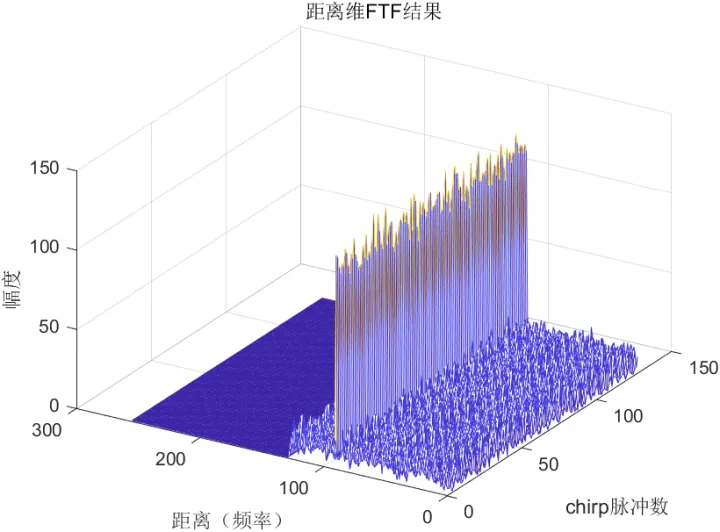

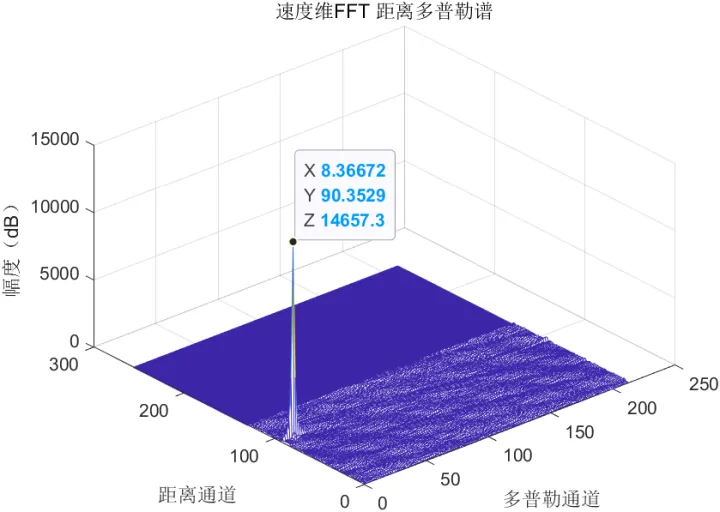

仿真代码分析

（1）设置雷达参数：频段77GHz。

clear all;
close all;
clc;
%% 雷达系统参数设置
fc= 77e9;             % 雷达工作频率 载频
c = 3e8;              % 光速

%% FMCW波形参数设置
maxR = 200;           % 雷达最大探测目标的距离
rangeRes = 1;         % 雷达的距离分率 
maxV = 20;            % 雷达最大检测目标的速度
B = c/(2*rangeRes);       % 发射信号带宽 (y-axis)  B = 150MHz
Nd=128;                          %chirp数量 
Nr=256;                        %ADC采样点数
Tchirp = 5 * 2 * maxR/c;  % 扫频时间 (x-axis), 5.5= sweep time should be at least 5 o 6 times the round trip time
endle_time=2.5e-6;          %空闲时间

vres=(c/fc)/(2*Nd*(Tchirp+endle_time));%速度分辨率

（2）用户自定义参数：距离门和速度门

这里为了保证距离和速度仿真出来的计算结果是符合理论的，要求设置参数时需要考虑分辨率。

%% 用户自定义目标参数
r0 = rangeRes*90;  % 目标距离 rangeRes*距离通道号 距离通道号范围[1 256]
v0 = vres*5        % 目标速度 vres*速度通道号[1 128]

v0 = 8.3014

（3）雷达发射信号、回波信号、混频处理：

slope = B / Tchirp;         %调频斜率
f_IFmax= (slope*2*maxR)/c ; %最高中频频率
f_IF=(slope*2*r0)/c ;       %当前中频频率
% Nr=1024*256;                %和频信号点数设置
Fs=Nr/Tchirp;                 %模拟信号采样频率

%%
t=linspace(0,Nd*Tchirp,Nr*Nd); %发射信号和接收信号的采样时间，在MATLAB中的模拟信号是通过数字信号无限采样生成的。
Tx=zeros(1,length(t)); %发射信号
Rx=zeros(1,length(t)); %接收信号
Mix = zeros(1,length(t)); %差频、差拍、拍频、中频信号
r_t=zeros(1,length(t));
td=zeros(1,length(t));
%% 动目标信号生成
for i=1:length(t)
    r_t(i) = r0 + v0*t(i); % 距离更新
    td(i) = 2*r_t(i)/c;    % 延迟时间
    
    Tx(i) = cos(2*pi*(fc*t(i) + (slope*t(i)^2)/2)); % 发射信号 实数信号
    Rx(i) = cos(2*pi*(fc*(t(i)-td(i)) + (slope*(t(i)-td(i))^2)/2)); %接收信号 实数信号
    
    if i<=1024
        freq(i)=fc+slope*i*Tchirp/Nr; %发射信号时频图 只取第一个chirp
        freq_echo(i)=fc+slope*i*Tchirp/Nr;%回波信号频谱延迟
    end
    
    Mix(i) = Tx(i).*Rx(i);%差频、差拍、拍频、中频信号
end

（4）希尔伯特变换

signal = reshape(Mix,Nr,Nd);

MixIQ=zeros(Nr,Nd);
for i=1:Nd
    
    MixIQ(:,i) =hilbert(Mix(((i-1)*Nr+1):Nr*i)); % 希尔伯特变换 变为IQ正交信号
    
end

（5）距离维FFT

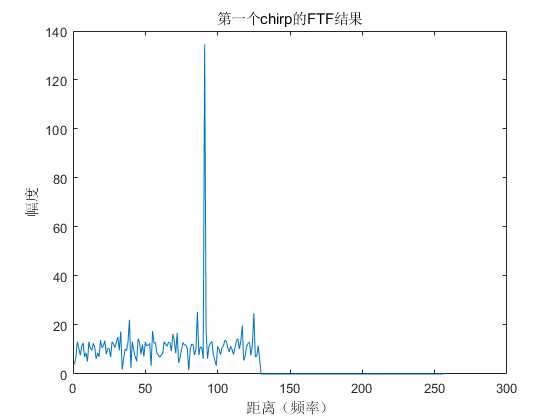

sig_fft1 = zeros(Nr,Nd);
for k=1:Nd
    sig_fft1(:,k)=fft(MixIQ(:,k));
end

sig_fft = abs(sig_fft1);
figure;
plot(sig_fft(:,1));
xlabel('距离（频率）');
ylabel('幅度')
title('第一个chirp的FTF结果')

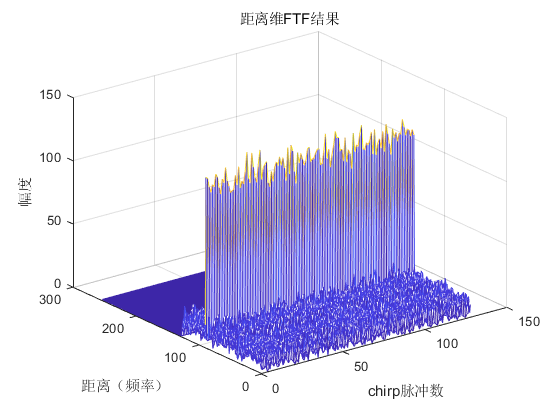


%% 距离FFT结果谱矩阵
figure;
mesh(sig_fft);
ylabel('距离（频率）');
xlabel('chirp脉冲数')
zlabel('幅度')
title('距离维FTF结果')

（6）速度维FFT

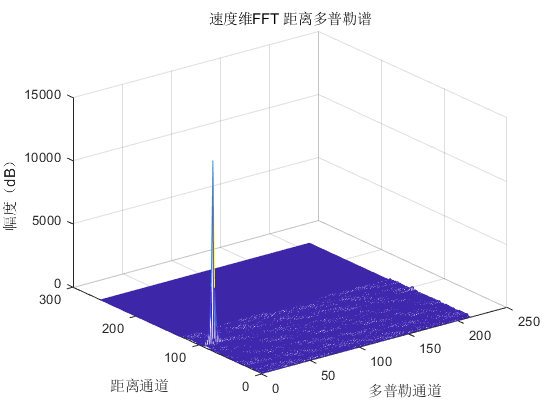

%% 速度维FFT
sig_fft2 = zeros(Nr,Nd);
for k=1:Nr
    sig_fft2(k,:)=fft(sig_fft1(k,:));
end

% sig_fft2 = fft2(MixIQ);
RDM = abs(sig_fft2);
doppler_axis = linspace(0,128,Nd)*vres;
range_axis = linspace(0,256,Nr)*rangeRes;

figure;
mesh(doppler_axis,range_axis,RDM);
xlabel('多普勒通道'); ylabel('距离通道'); zlabel('幅度（dB）');
title('速度维FFT 距离多普勒谱');

# FMCW雷达的距离多普勒估计

[代码分享 | 利用MATLAB实现FMCW雷达的距离多普勒估计 (qq.com)](https://mp.weixin.qq.com/s?__biz=MzkxMTMwMTg4Mg==&mid=2247485592&idx=1&sn=506b33c4b480edb95d6f4a58e401c050&chksm=c11f050df6688c1b5623e88308b2c1df9572cfee6cb70a411221f4898e2f579de2e18ac68504&scene=178&cur_album_id=2345254053418745857#rd)

分享一个简单的FMCW雷达单目标仿真代码，包含雷达发射信号、接收信号、混频、距离维FFT、速度维FFT、二维CA-CFAR检测等。

代码我调整过，要比之前分享过的要简洁，FMCW雷达原理我就不讲了，具体看这篇文章：[毫米波雷达入门](http://mp.weixin.qq.com/s?__biz=MzkxMTMwMTg4Mg==&mid=2247484237&idx=1&sn=218acaf9238decffcbb0706bd8bd845f&chksm=c11f0ed8f66887ce114b3bc4369fb579907671fbd029f3d6e9eb390d915ae4d760004231d0fc&scene=21#wechat_redirect)。

clear all;
clc;
close all;
%% Radar Specifications 
c = 3e8;
fc= 77e9;             %carrier freq                                                        
Nd=128;                
Nr=256; 
lamuda = c/fc;
%% User Defined Range and Velocity of target
range = 100;
vel = 1;
Tchirp = 40e-6;
range_res = 1;
max_vel = lamuda/(4*Tchirp);% m/s

%% FMCW Waveform Generation
B = c / (2*range_res);
vel_res = lamuda/(2*Tchirp*Nd);
slope = B/Tchirp;
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples
r_t=zeros(1,length(t));

td = 2 * (range + vel*t)/ c;
Tx  = exp(1j*2*pi*(fc*t + (slope*t.*t)/2 ) );
Rx  = exp(1j*2*pi*(fc*(t -td) + (slope * (t-td).*(t-td))/2 ) );
Mix = Tx.*conj(Rx);%混频

Mix_fft1d =Mix+awgn(Mix,20);%增加高斯白噪声
Mix_fft1d = reshape(Mix_fft1d, [Nr, Nd]);


（1）原始信号，256个采样点，128个脉冲。

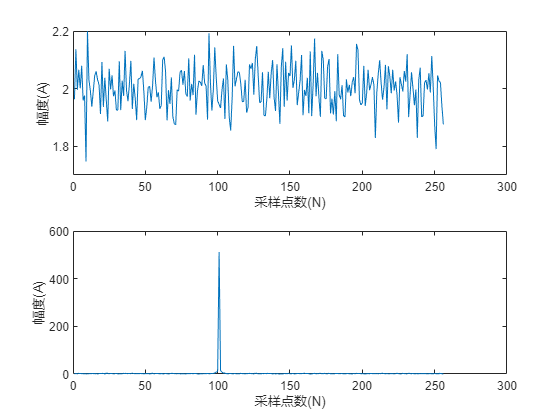

%%原始信号
figure(1);
subplot(2,1,1);
plot(abs((Mix_fft1d(:,1))));
xlabel('采样点数(N)')
ylabel('幅度(A)')
subplot(2,1,2);
plot(abs(fft(Mix_fft1d(:,1))));
xlabel('采样点数(N)')
ylabel('幅度(A)')

signal_fft = fft(Mix_fft1d, Nr);

（2）距离维FFT

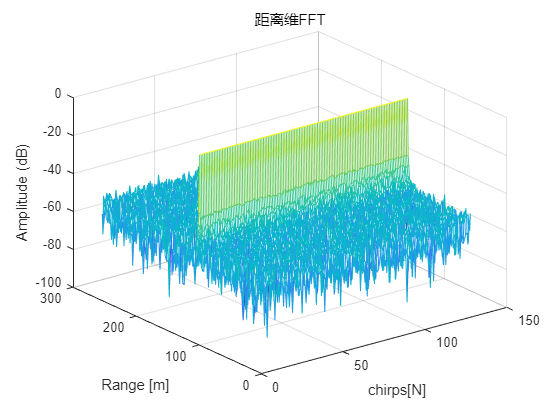

figure(2)
mesh(db(abs(signal_fft./max(signal_fft))));
title('Range from First FFT');
ylabel('Range [m]');
xlabel('chirps[N]')
zlabel('Amplitude (dB)');
title('距离维FFT')

for i=1:Nr
    signal_fft2(i,:) = fftshift(fft(signal_fft(i,:)));
end
doppler_axis = vel_res*((-Nd/2:(Nd-1)/2)-1);
range_axis = range_res*((1:Nr)-1);

3）速度维FFT

目标设定距离维100米，速度为1m/s，该参数可以修改。

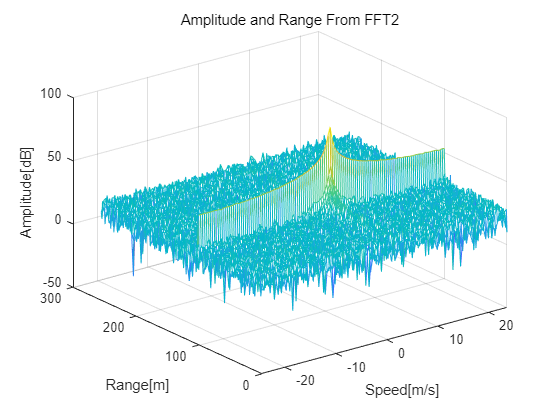

figure(3);
mesh(doppler_axis,range_axis,db(abs(signal_fft2)));
xlabel('Speed[m/s]');
ylabel('Range[m]');
zlabel('Amplitude[dB]');
title('Amplitude and Range From FFT2');


%% CFAR implementation
RDM =(abs(signal_fft2));
n_train_cells = 8;
n_train_bands = 8;
%test (CUT) for accurate estimation
n_guard_cells = 4;
n_guard_bands = 4;
offset = 1.4;
noise_level = zeros(1,1);
RDM = RDM / max(RDM(:));
for row0 = n_train_cells + n_guard_cells + 1 : Nr - (n_train_cells + n_guard_cells)
  for col0 = n_train_bands + n_guard_bands + 1 : (Nd) - (n_train_bands + n_guard_bands)
    noise_level = zeros(1, 1);
    for row1 = row0 - (n_train_cells + n_guard_cells) : row0 + (n_train_cells + n_guard_cells)
      for col1 = col0 - (n_train_bands + n_guard_bands) : col0 + (n_train_bands + n_guard_bands)
        if (abs(row0 - row1) > n_guard_cells || abs(col0 - col1) > n_guard_bands)
          noise_level = noise_level + db2pow(RDM(row1, col1));
        end
      end
    end
    % Calculate threshold from noise average then add the offset
    thresh = pow2db(noise_level / (2 * (n_train_bands + n_guard_bands + 1) * 2 * (n_train_cells + n_guard_cells + 1) - (n_guard_cells * n_guard_bands) - 1));
    thresh = thresh + offset;

    CUT = RDM(row1-(n_train_cells + n_guard_cells) ,col1-(n_train_bands + n_guard_bands));
    if (CUT < thresh)
      RDM(row0, col0) = 0;
else
      RDM(row0, col0) = 1;
    end

  end
end

RDM(RDM~=0 & RDM~=1) = 0;

（4）CA-CFAR

距离维一次，速度维一次，两次CA-CFAR。

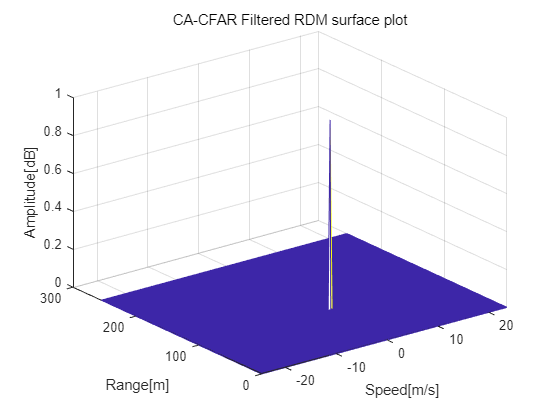

figure('Name', 'CA-CFAR Filtered RDM')
mesh(doppler_axis,range_axis,RDM);
title( 'CA-CFAR Filtered RDM surface plot');
xlabel('Speed[m/s]');
ylabel('Range[m]');
zlabel('Amplitude[dB]');